filelistPP = ["Position_control_PP_29-Apr-2025_15-52-56.mat", "Position_control_PP_29-Apr-2025_15-57-33.mat", "Position_control_PP_29-Apr-2025_15-59-58.mat", "Position_control_PP_29-Apr-2025_16-05-57.mat", "Position_control_PP_29-Apr-2025_16-06-47.mat", "Position_control_PP_29-Apr-2025_16-08-04.mat", "Position_control_PP_29-Apr-2025_16-15-38.mat", "Position_control_PP_29-Apr-2025_16-19-46.mat", "Position_control_PP_29-Apr-2025_16-21-40.mat", "Position_control_PP_29-Apr-2025_16-27-10.mat", "Position_control_PP_29-Apr-2025_16-42-20.mat", "Position_control_PP_29-Apr-2025_16-47-32.mat", "Position_control_PP_29-Apr-2025_16-51-46.mat", "Position_control_PP_29-Apr-2025_16-53-53.mat", "Position_control_PP_29-Apr-2025_16-56-11.mat", "Position_control_PP_29-Apr-2025_17-06-15.mat", "Position_control_PP_29-Apr-2025_17-07-34.mat", "Position_control_PP_29-Apr-2025_17-09-36.mat", "Position_control_PP_29-Apr-2025_17-12-23.mat", "Position_control_PP_29-Apr-2025_17-24-13.mat", "Position_control_PP_29-Apr-2025_17-27-12.mat", "Position_control_PP_29-Apr-2025_17-36-36.mat", "Position_control_PP_29-Apr-2025_17-44-09.mat", "Position_control_PP_29-Apr-2025_17-52-13.mat", "Position_control_PP_29-Apr-2025_17-54-56.mat", "Position_control_PP_29-Apr-2025_17-57-36.mat", "Position_control_PP_29-Apr-2025_17-59-27.mat", "Position_control_PP_29-Apr-2025_18-02-38.mat", "Position_control_PP_29-Apr-2025_18-04-42.mat", "Position_control_PP_29-Apr-2025_18-07-34.mat", "Position_control_PP_29-Apr-2025_18-09-31.mat", "Position_control_PP_29-Apr-2025_18-15-12.mat", "Position_control_PP_29-Apr-2025_18-17-45.mat", "Position_control_PP_29-Apr-2025_18-21-45.mat", "Position_control_PP_29-Apr-2025_18-22-36.mat", "Position_control_PP_29-Apr-2025_18-25-08.mat", "Position_control_PP_29-Apr-2025_18-28-11.mat", "Position_control_PP_29-Apr-2025_18-31-08.mat", "Position_control_PP_29-Apr-2025_18-34-28.mat", "Position_control_PP_29-Apr-2025_18-35-20.mat", "Position_control_PP_29-Apr-2025_18-36-40.mat", "Position_control_PP_29-Apr-2025_18-39-17.mat", "Position_control_PP_29-Apr-2025_18-49-00.mat", "Position_control_PP_29-Apr-2025_18-51-45.mat", "Position_control_PP_29-Apr-2025_18-54-05.mat", "Position_control_PP_29-Apr-2025_18-55-32.mat", "Position_control_PP_29-Apr-2025_18-57-08.mat", "Position_control_PP_29-Apr-2025_18-59-52.mat"];
i = 31

i = 31

file = filelistPP(i);
data = load("lab6/data/PP/"+file).data;
% smartPlotLab6_PP(data,i+") "+file)

t = data(1,:);
a1 = data(2,:);
a2 = data(3,:)+pi/2;
a1r = data(10,:);
a2r = data(11,:)+pi/2;

A = 0.08;

wl = [1,2,3,4, 5,6]

wl =      1     2     3     4     5     6


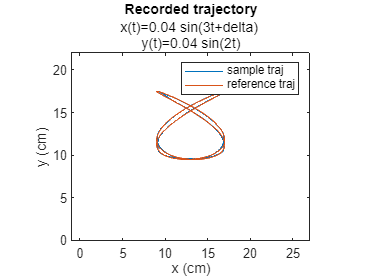

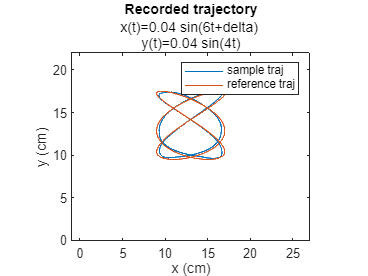

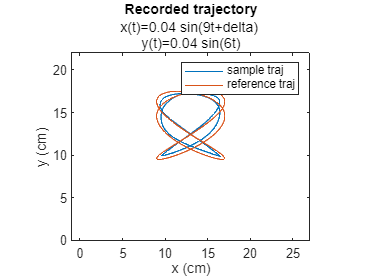

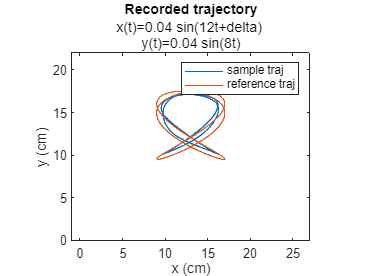

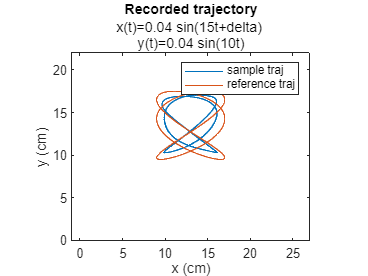

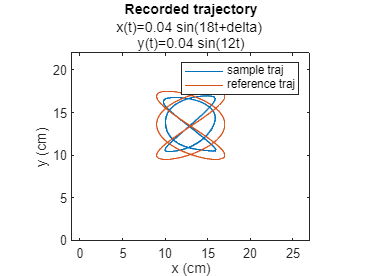

wx = 3*wl;
wy = 2*wl;
k = 1;

for i = 0:10:50
    id_start = time2index(i)+500;
    id_end = time2index(i+10)-500;
    t_s=t(id_start:id_end);
    a1_s = a1(id_start:id_end);
    a2_s = a2(id_start:id_end);
    a1_r = a1r(id_start:id_end);
    a2_r = a2r(id_start:id_end);
    % figure
    % plot(t_s,a1_s)
    % hold on
    % plot(t_s,a1_r)
    % hold off
    % 
    % figure
    % plot(t_s,a2_s-pi/2)
    %  hold on
    % plot(t_s,a2_r-pi/2)
    % hold off
    % figure
    x_string = "x(t)=0.04 sin("+wx(k)+"t+delta) ";
    y_string = "y(t)=0.04 sin("+wy(k)+"t)";

    figure
    printXYtrajectory(a1_s,a2_s)
    hold on
    printXYtrajectory(a1_r,a2_r)
    legend(["sample traj","reference traj"])
    title("Recorded trajectory")
    subtitle([x_string,y_string])
    k = k+1;
end